clc;clear;
% close all

directory = 'C:\Storage\OneDrive - University of Southern California\Documents\USC\WiDes\Projects\1st Year\COSMOS\SB1 Files\host\demos\basic\Result\';


group_ID = 2;
directory = [directory, 'Group_', num2str(group_ID)];

for subgroup_ID = 1:6
    for measurement_ID = 1:4
        eval(['data_', num2str(group_ID), '_', num2str(subgroup_ID), '_', num2str(measurement_ID), ' = load("', directory, '\data_', num2str(group_ID), '_', num2str(subgroup_ID), '_', num2str(measurement_ID), '.mat");'])
    end
end
clear subgroup_ID  measurement_ID  directory

## 1 Evaluation A:  Recover the COSMOS Evaluation Process

% 
% 
% % rxfd = circshift(rxfd, 512);
% 
% % Plot
% legendInfo = cell(N_frame, 1);
% 
% figure
% hold on
% for i = 1:N_frame
%     plot(-N_fft/2:N_fft/2-1, 20*log10(abs(shifted_fd(:, i))));
%     legendInfo{i} = ['frame ' num2str(i)]; 
% end
% % plot(-512:1:511, 20*log10(abs(RxSignalFreqDomain(:, 1))));
% y_min = min(mean(20*log10(abs(fd)))) - 20;
% y_max = max(max(20*log10(abs(fd)))) + 20;
% ylim([y_min, y_max])
% title(['Received Signal of Measurement ', num2str(group_ID), '\_', num2str(subgroup_ID), '\_', num2str(measurement_ID), ', COSMOS version'])
% xlabel('Subcarrier Index')
% ylabel('Magnitude [dB]')
% grid minor
% legend(legendInfo)
% 
% clear i  y_min  y_max  ans  legendInfo

## 2 Evaluation B: 

Subgroup 1

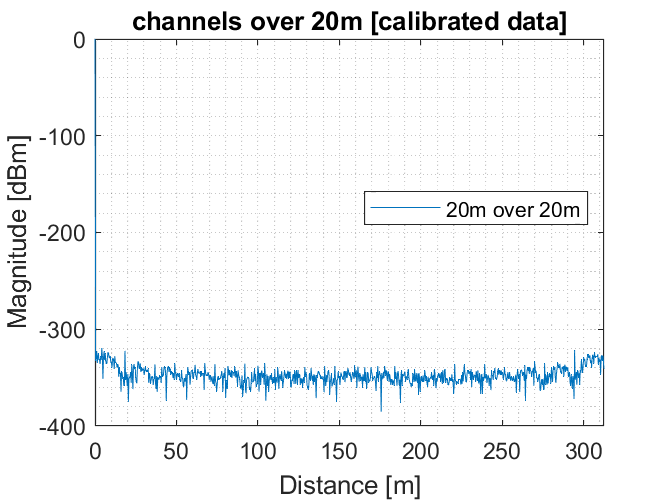

subgroup = 2;

% crop_range = data_2_4_1.crop_range;
% BW = data_2_4_1.BW;
eval(['crop_range = data_', num2str(group_ID), '_', num2str(subgroup) '_1.crop_range;'])
eval(['BW = data_', num2str(group_ID), '_', num2str(subgroup) '_1.BW;'])
tau_max = (length(crop_range)-1) / BW;
tau_step = tau_max / (length(crop_range)-1);
tau = 0 : tau_step : tau_max;

ref_ID = 1;
ref = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(ref_ID)];

figure
meas_ID = 1;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_1_1.fd_cropped ./ data_2_1_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))
legend('20m over 20m', 'Location', 'best')
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title('channels over 20m [calibrated data]')
grid minor

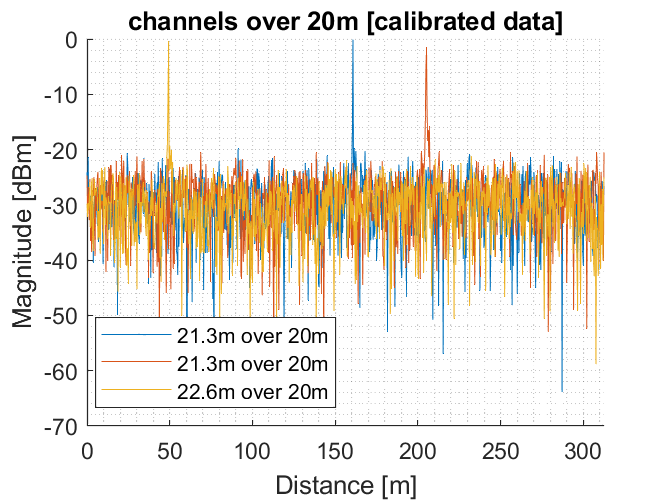


% ================================
figure
hold on
meas_ID = 2;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_1_2.fd_cropped ./ data_2_1_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))

meas_ID = 3;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_1_3.fd_cropped ./ data_2_1_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))

meas_ID = 4;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_1_4.fd_cropped ./ data_2_1_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))


legend('21.3m over 20m', '21.3m over 20m', '22.6m over 20m', 'Location', 'best')
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title('channels over 20m [calibrated data]')
grid minor

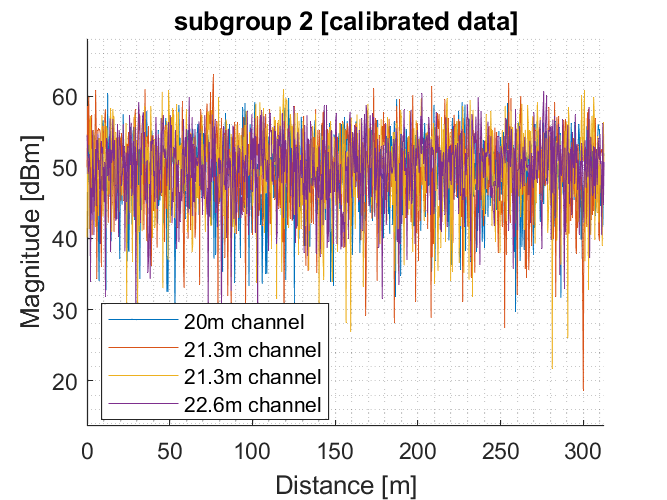

% ================================



legendInfo = cell(4, 1);
% distance
figure
hold on
y_max = zeros(4, 1);
y_min = zeros(4, 1);
for i = 1:4
    eval(['data = data_', num2str(group_ID), '_', num2str(subgroup), '_', num2str(i), ';'])
    td_cropped = ifft(data.fd_cropped(:, 1));
    plot(tau*3e8, 20*log10(abs(td_cropped)));
    y_max(i) = max(20*log10(abs(td_cropped)));
    y_min(i) = min(20*log10(abs(td_cropped)));
    legendInfo{i} = [num2str(data.distance), 'm channel']; 
end
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title(['subgroup ', num2str(subgroup), ' [calibrated data]'])
legend(legendInfo, 'Location', 'best')
grid minor
ylim([min(y_min)-5, max(y_max)+5])

Subgroup 4

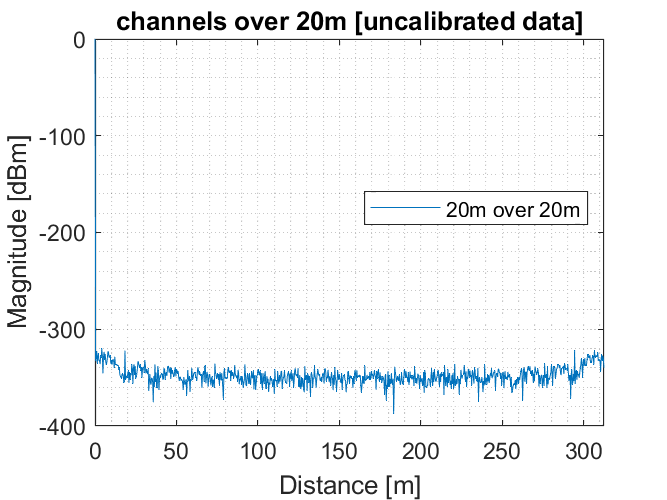

subgroup = 5;

eval(['crop_range = data_', num2str(group_ID), '_', num2str(subgroup) '_1.crop_range;'])
eval(['BW = data_', num2str(group_ID), '_', num2str(subgroup) '_1.BW;'])
tau_max = (length(crop_range)-1) / BW;
tau_step = tau_max / (length(crop_range)-1);
tau = 0 : tau_step : tau_max;

ref_ID = 1;
ref = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(ref_ID)];

figure
meas_ID = 1;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_4_1.fd_cropped ./ data_2_4_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))
legend('20m over 20m', 'Location', 'best')
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title('channels over 20m [uncalibrated data]')
grid minor

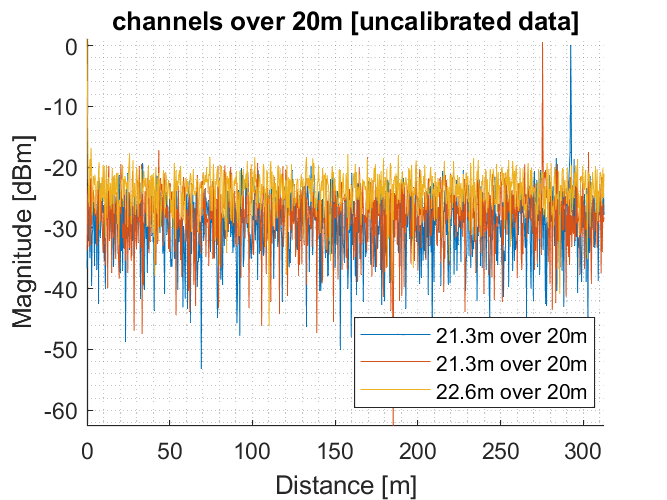


% ================================
figure
hold on
meas_ID = 2;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_4_2.fd_cropped ./ data_2_4_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))

meas_ID = 3;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_4_3.fd_cropped ./ data_2_4_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))

meas_ID = 4;
meas = [num2str(group_ID), '_', num2str(subgroup), '_', num2str(meas_ID)];
% fd_cal = data_2_4_4.fd_cropped ./ data_2_4_1.fd_cropped;
eval(['fd_cal = data_', meas, '.fd_cropped(:, 1) ./ data_', ref, '.fd_cropped(:, 1);'])
td_cal = ifft(fd_cal);
plot(tau*3e8, 20*log10(abs(td_cal)))


legend('21.3m over 20m', '21.3m over 20m', '22.6m over 20m', 'Location', 'best')
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title('channels over 20m [uncalibrated data]')
grid minor

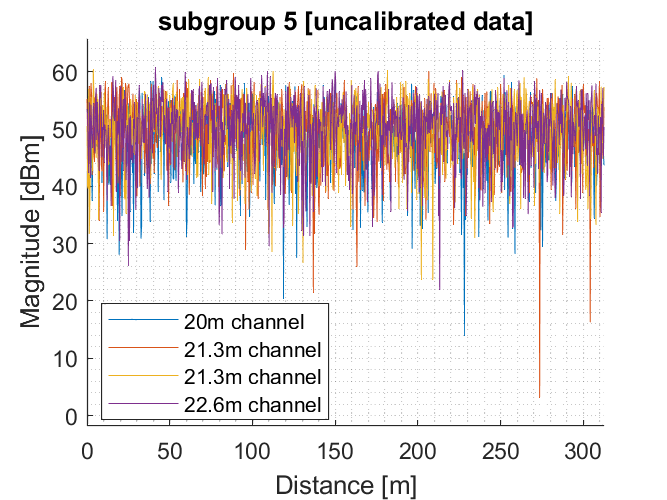

% ================================



legendInfo = cell(4, 1);
% distance
figure
hold on
y_max = zeros(4, 1);
y_min = zeros(4, 1);
for i = 1:4
    eval(['data = data_', num2str(group_ID), '_', num2str(subgroup), '_', num2str(i), ';'])
    td_cropped = ifft(data.fd_cropped(:, 1));
    plot(tau*3e8, 20*log10(abs(td_cropped)));
    y_max(i) = max(20*log10(abs(td_cropped)));
    y_min(i) = min(20*log10(abs(td_cropped)));
    legendInfo{i} = [num2str(data.distance), 'm channel']; 
end
xlabel('Distance [m]')
ylabel('Magnitude [dBm]')
title(['subgroup ', num2str(subgroup), ' [uncalibrated data]'])
legend(legendInfo, 'Location', 'best')
grid minor
ylim([min(y_min)-5, max(y_max)+5])





% 
% figure;
% hold on
% for i = 1:N_frame
%     plot(20*log10(abs(shifted_fd(:, i))))
% end
% y_min = min(mean(20*log10(abs(fd)))) - 20;
% y_max = max(max(20*log10(abs(fd)))) + 20;
% ylim([y_min, y_max])
% title(['Received Signal of Measurement ', num2str(group_ID), '\_', num2str(subgroup_ID), '\_', num2str(measurement_ID), ', COSMOS version'])
% xlabel('Sample Index')
% ylabel('Magnitude [dB]')
% grid minor
% 
% 
% crop_range = (N_fft/2 + sc_min + 1  :  N_fft/2 + sc_max + 1)';
% fd_cropped = shifted_fd(crop_range, :);
% td_cropped = ifft(fd_cropped);
% 

% 
% 
% figure
% plot(tau*3e8, 20*log10(abs(td_cropped)))
% 
% fd_cropped_temp = fd_cropped;
% load('LoS_20m.mat')
% fd_cal = fd_cropped_temp ./ fd_cropped;
% td_cal = ifft(fd_cal);
% figure
% plot(tau*3e8, 20*log10(abs(td_cal)))